## Question 1

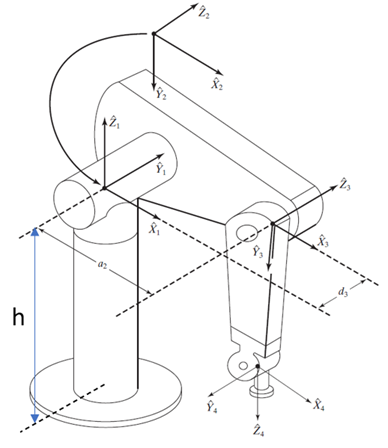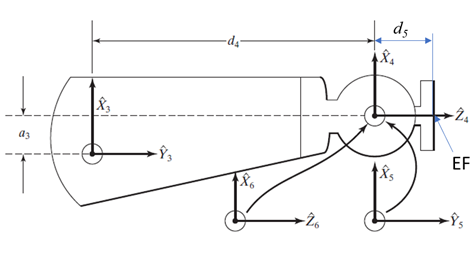

### Desire Path generation

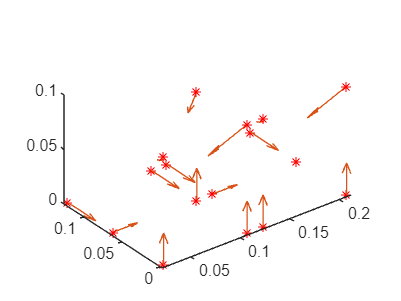

clear
clc

load hershey
letter_1 = hershey{'H'};
letter_2 = hershey{'H'};
scale = 0.15;
moving_up = 0.1;

p1 = [scale*letter_1.stroke; zeros(1,size(letter_1.stroke,2))];
k = find(isnan(p1(1,:)));
p1(:,k) = p1(:,k-1); p1(3,k) = moving_up;

p2 = [scale*letter_2.stroke; zeros(1,size(letter_2.stroke,2))];
k = find(isnan(p2(1,:)));
p2(:,k) = p2(:,k-1); p2(3,k) = moving_up;

% shift the second letter to the left
distance = 0.1;
p2(1,:) = p2(1,:) + distance;

% create intermediate via points between letter
p_middle =[[p1(1,end) p1(2,end) moving_up];[p2(1,1) p2(2,1) 0]]';

% Concatenate the waypoint
p = [p1 p_middle p2];


figure
plot3(p(1,:),p(2,:),p(3,:),"*r");
hold on
quiver3(p(1,1:(end-1)),p(2,1:(end-1)),p(3,1:(end-1)),diff(p(1,:)),diff(p(2,:)),diff(p(3,:)))
axis equal

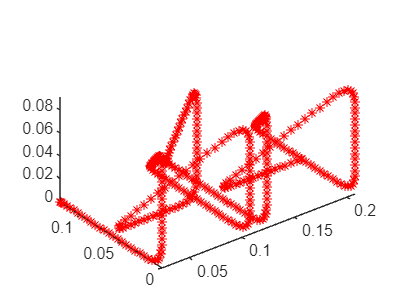


% figure
% plot(p(:,1),p(:,2),"*r")
% axis equal

% generate the trajectory
% sample time
dt = 0.02;
axis_speed_limit = 0.5;
acceleration_time = 0.2;
traj = mstraj(p(:,1:end)',[axis_speed_limit axis_speed_limit axis_speed_limit],[],p(:,1)',dt,acceleration_time);
figure
plot3(traj(:,1),traj(:,2),traj(:,3),"*r")
axis equal

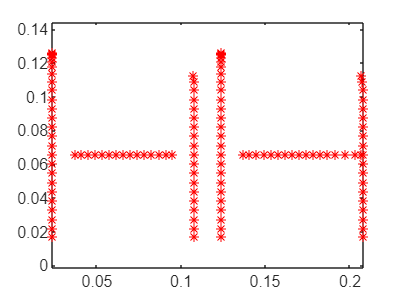


% filter out the plot the result on 2D
filtered_2D_point =[];
index =1;
for i = 1:1:length(traj)
    if (traj(i,3)<0.001)
        filtered_2D_point(index,1) = traj(i,1);
        filtered_2D_point(index,2) = traj(i,2);
        index = index +1;
    end
end

figure
plot(filtered_2D_point(:,1),filtered_2D_point(:,2),"*r")
axis equal


save Letter_HH_trajectory.mat traj